# Performance evaluation: ROC curves

You are working on a project to classify between cancerous (malignant) and healthy (benign) biopsies. Your colleague has shared two trained classifiers with you and some previously unseen testing data:

clear all;
load('classifiers.mat', 'm_nb', 'm_dt', 'test_examples', 'test_labels');

Your task is to analyse the True Positive Rate (TPR) and False Positive Rate (FPR) for each classifier in order to make a decision about which one is performing best.

Marks are available for:

- Using each classifier to predict labels and associated likelihood scores for the test data [4 marks]

- Computing the TPR for each classifier, taking "malignant" as the positive class [3 marks]

- Computing the FPR for each classifier, taking "malignant" as the positive class [3 marks]

- Generating a Receiver Operating Characteristic (ROC) curve for each classifier and plotting them together on a single graph with a legend and labelled axes [4 marks]

- Deciding on the best classifier based on a sensible quantitative comparison between the ROC curves [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

% add as many lines of code as you need below:

clear all;
load('classifiers.mat', 'm_nb', 'm_dt', 'test_examples', 'test_labels');

% use our traning confusion matrices classifier to classify the testing
% data
[predictions, scores_dt] = predict(m_dt, test_examples);
[predictions, scores_nb] = predict(m_nb, test_examples);

scores_dt(:, 2)

ans =      1
     1
     0
     0
     1
     1
     0
     0
     1
     0


scores_nb(:, 2)

ans =     1.0000
    1.0000
    0.0000
    0.0000
    1.0000
    1.0000
    0.0000
    0.0000
    1.0000
    0.0000



% output a confusion matrix:
[c,order] = confusionmat(test_labels, predictions)

c =     83     2
     4    53


order = 2×1 categorical array
     Benign 
     Malignant 



% calculates the TPR
TPR = c(2,2) / ( c(2,2) + c(2,1) )

TPR = 0.9298

% calculates the FPR
FPR = c(1,2) / (c(1,2) + c(1,1))

FPR = 0.0235

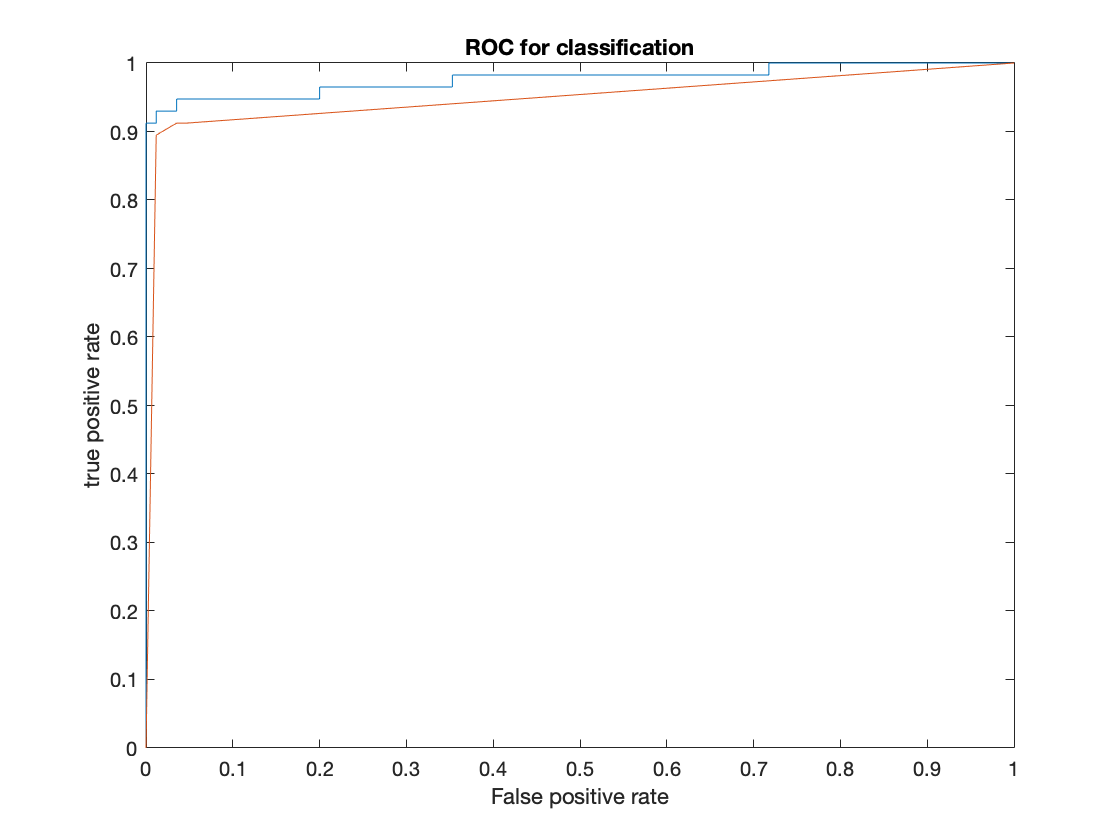


%string_pos equals benign or malignant
string_pos = 'Malignant';

[X,Y] = perfcurve(test_labels,scores_nb(:,2) , "Malignant");
plot(X,Y)
hold on 
    xlabel('False positive rate')
    ylabel('true positive rate')
    title('ROC for classification')
   [x,y] = perfcurve(test_labels, scores_dt(:,2), "Malignant");
   plot(x, y)